The following simple ODE uncovers a surprise. 

f = @(t,u) u.^2 - u.^3;
u0 = 0.005;

We will solve the problem first with the implicit AM2 method using $n=200$ steps.

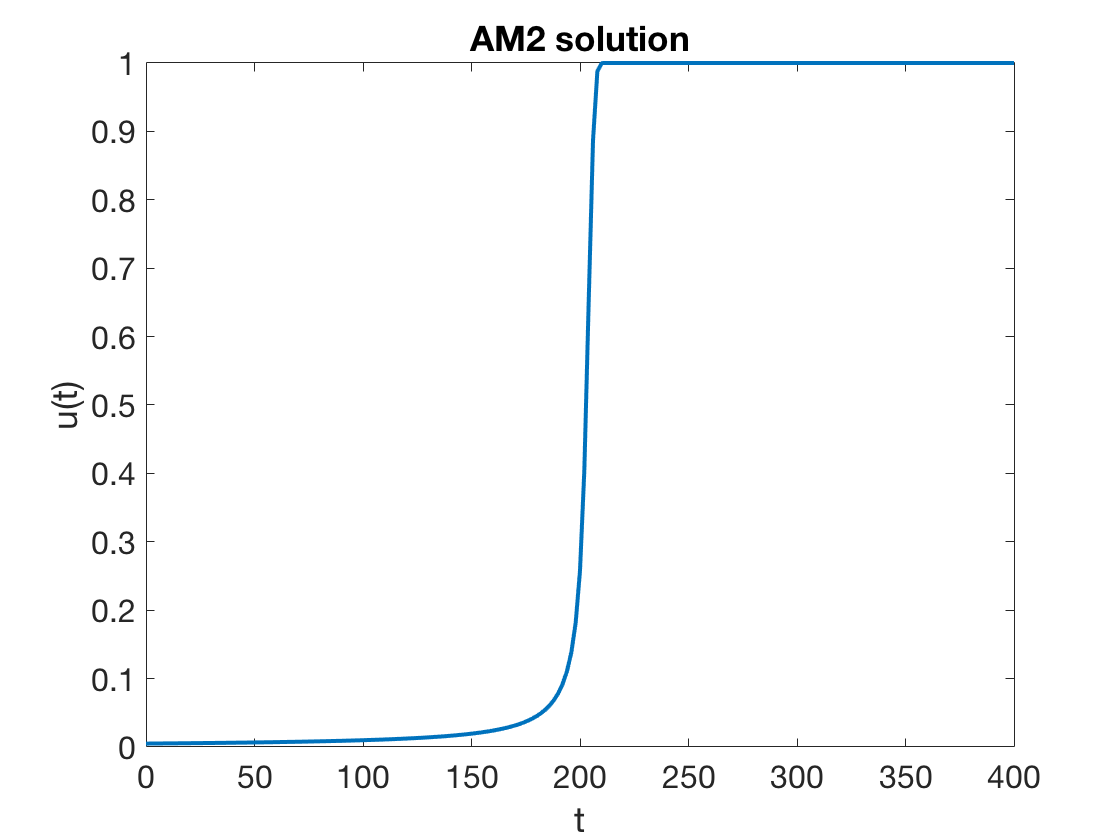

[tI,uI] = am2(f,[0 400],u0,200);
plot(tI,uI)
xlabel('t'), ylabel('u(t)')   % ignore this line
title('AM2 solution')   % ignore this line

Now we repeat the process using the explicit AB4 method.

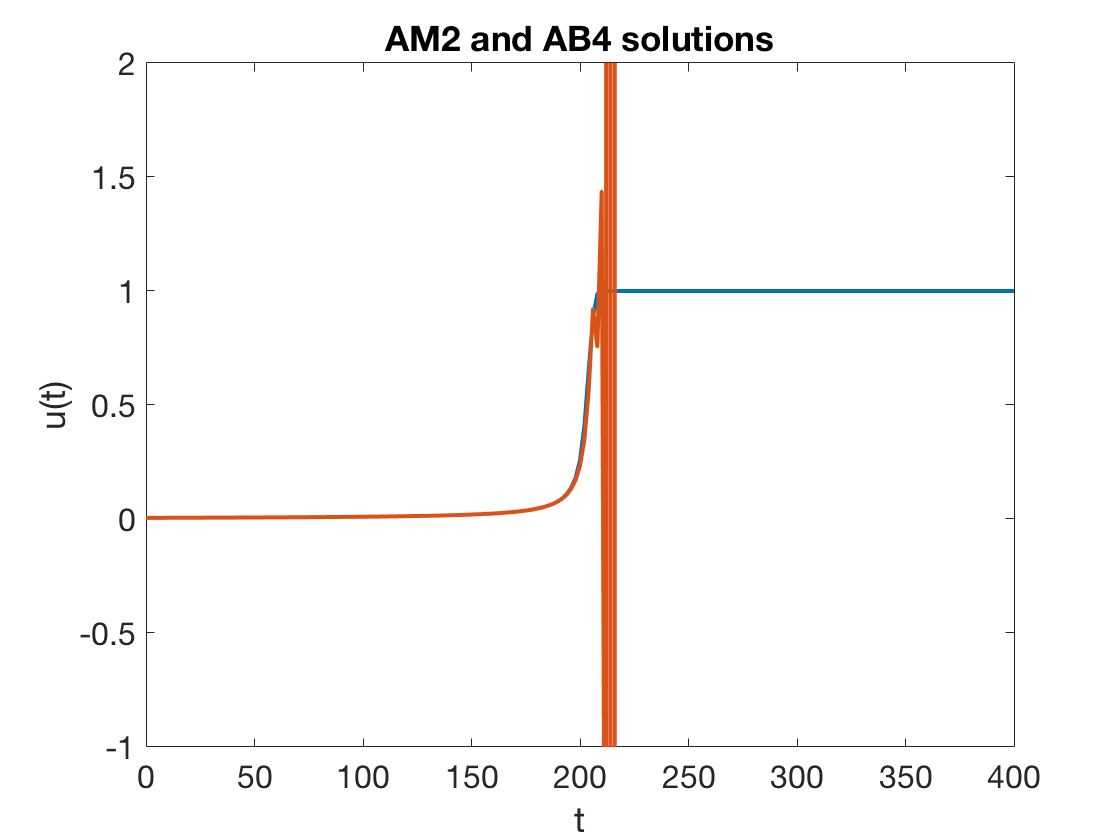

[tE,uE] = ab4(f,[0 400],u0,200);
hold on, plot(tE,uE), ylim([-1 2])
title('AM2 and AB4 solutions')  % ignore this line

Once the solution starts to take off, the AB4 result goes catastrophically wrong.

format short e, uE(105:111)

ans =    7.5539e-01
   1.4373e+00
  -3.2890e+00
   2.1418e+02
  -4.4821e+07
   4.1269e+23
  -3.2214e+71


We hope that AB4 will converge in the limit $h\to 0$, so let's try using more steps.

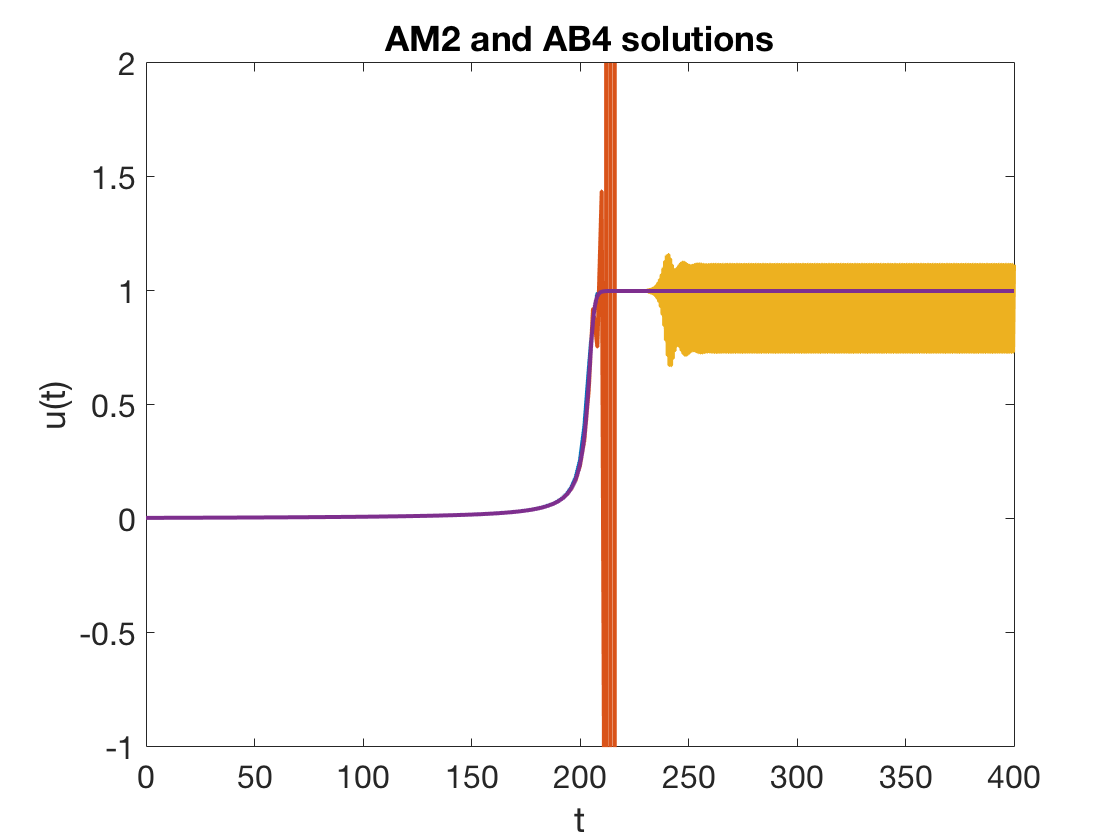

for n = [1000 1600]
    [tE,uE] = ab4(f,[0 400],u0,n);
    plot(tE,uE)
end

So AB4, which is supposed to be *more* accurate than AM2, actually needs something like 8 times as many steps to get a reasonable-looking answer!